# Sygnał pobudzenia

#init

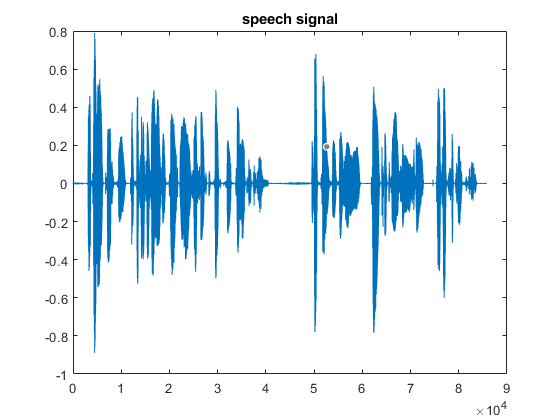

[x,fpr]=audioread('mowa1.wav');	
plot(x); title('speech signal')

% soundsc(x,fpr);			

N=length(x);	
Mlen=240;	
Mstep=180;	
Np=10;		
gdzie=Mstep+1;	

lpc=[];				
s=[];				
ss=[];				
bs=zeros(1,Np);			
Nramek=floor((N-Mlen)/Mstep+1);	

loop

for nr = 1:Nramek
    
    n = 1+(nr-1)*Mstep : Mlen + (nr-1)*Mstep;
    bx = x(n);
    
    bx = bx - mean(bx);  
    for k = 0 : Mlen-1
        r(k+1) = sum( bx(1 : Mlen-k) .* bx(1+k : Mlen) ); 
    end
    
    offset=20; rmax=max( r(offset : Mlen) );	  
    imax=find(r==rmax);								   
     
    if ( rmax > 0.35*r(1) ) 
        T=imax; 
    else 
        T=0; 
    end 
    
    rr(1:Np,1)=(r(2:Np+1))';
    for m=1:Np
        R(m,1:Np)=[r(m:-1:2) r(1:Np-(m-1))];			
    end
    a=-inv(R)*rr;											
    wzm=r(1)+r(2:Np+1)*a;									
    H=freqz(1,[1;a]);	
    
    if (T~=0) gdzie=gdzie-Mstep; end					
    
    for n=1:Mstep
        % T = 70; % 0 lub > 25 - w celach testowych
        if( T==0)
            pob=2*(rand(1,1)-0.5); gdzie=(3/2)*Mstep+1;			
        else
            if (n==gdzie) pob=1; gdzie=gdzie+T;	   
            else pob=0; end
        end
        ss(n)=wzm*pob-bs*a;		
        bs=[ss(n) bs(1:Np-1) ];	
    end
    
    s = [s ss];			
    
end